# Parsing the Netlist

% Importing the netlist description of the circuits
[A0, b0] = mappNETLIST('prelabNetlist.txt', 0);
[A60, b60] = mappNETLIST('prelabNetlist.txt', 60);

x = A0\b0.';

## Experiment

% Testing Gaussian Elimenation and PLU Decomposition as methods of solving
% systemf os equations
[L0, U0, P0] = PLU(A0);
[L60, U60, P60] = PLU(A60);

G0 = GaussElimPivot(A0,b0)

G0 =   120.0000
  116.3636
  116.3636
         0
    7.2727
    7.2727
   -7.2727


P0 = PLUSolver(L0, U0, P0, b0)

P0 =   120.0000
  116.3636
  116.3636
         0
    7.2727
    7.2727
   -7.2727


G60 = GaussElimPivot(A60,b60)

G60 = 1.0e+02 *

   1.2000 + 0.0000i
   1.1762 - 0.0114i
   1.1790 - 0.0171i
   0.4326 + 0.5597i
   0.0475 + 0.0229i
   0.0466 - 0.0361i
  -0.0475 - 0.0229i


P60 = PLUSolver(L60, U60, P60, b60)

P60 = 1.0e+02 *

   1.2000 + 0.0000i
   1.1762 - 0.0114i
   1.1790 - 0.0171i
   0.4326 + 0.5597i
   0.0475 + 0.0229i
   0.0466 - 0.0361i
  -0.0475 - 0.0229i



% Creating Bode Plots for each solution
[G60M, G60A] = phasor(G60);
[P60M, P60A] = phasor(P60);

## Analysis

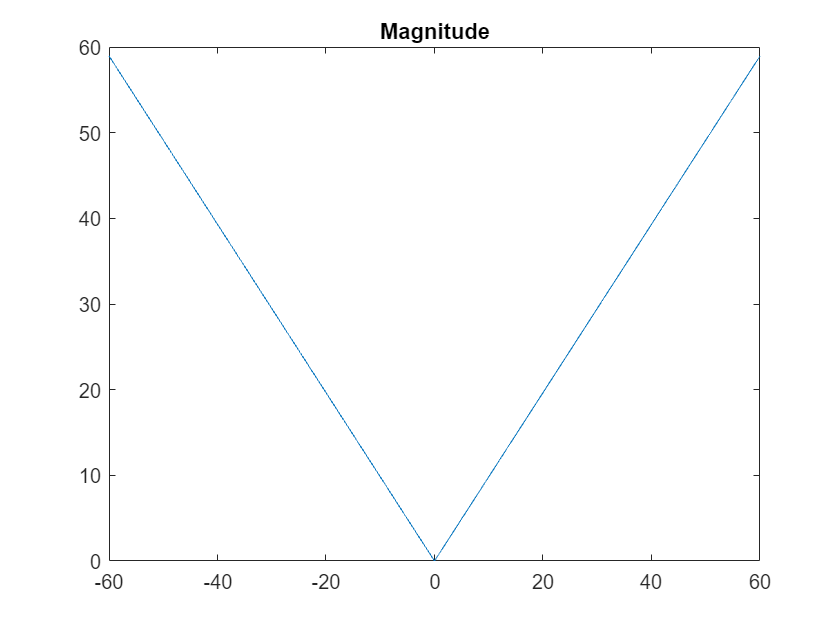

% Comparing the computing time of each algorithm
t0 = cputime;
[mSweep, aSweep] = gVoltageSweep(A60,b60);
t1 = cputime;
[mSweep, aSweep] = pVoltageSweep(A60,b60);
t2 = cputime;

disp("Guassian Elimination Time [sec]:")
disp(t1-t0)
disp("PLU Time [sec]:")
disp(t2-t1)

% Plotting the Sweep results
figure;
plot(-60:0.01:60, mSweep(3,:));
title('Magnitude');

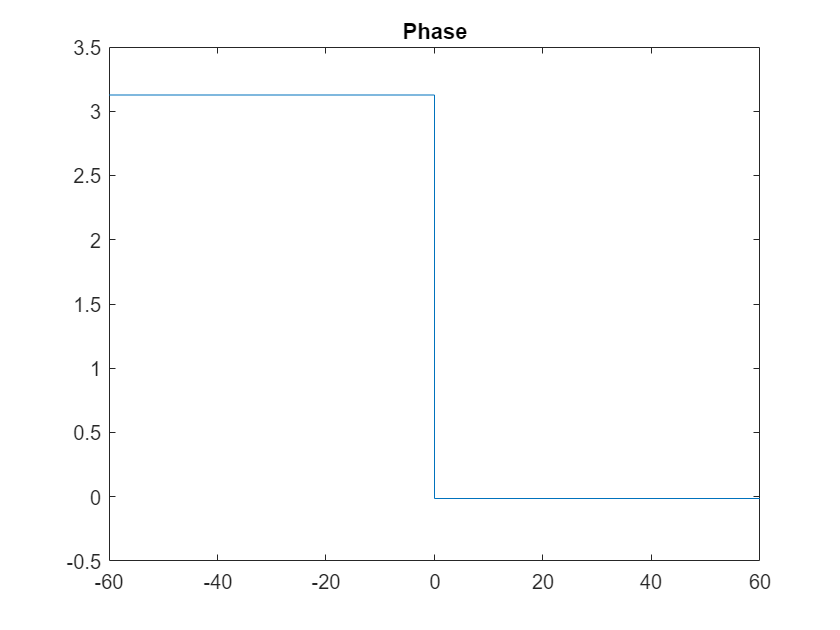

Guassian Elimination Time [sec]:


    2.5781



PLU Time [sec]:


    0.2188



figure;
plot(-60:0.01:60, aSweep(3,:));
title('Phase');

## Other Examples

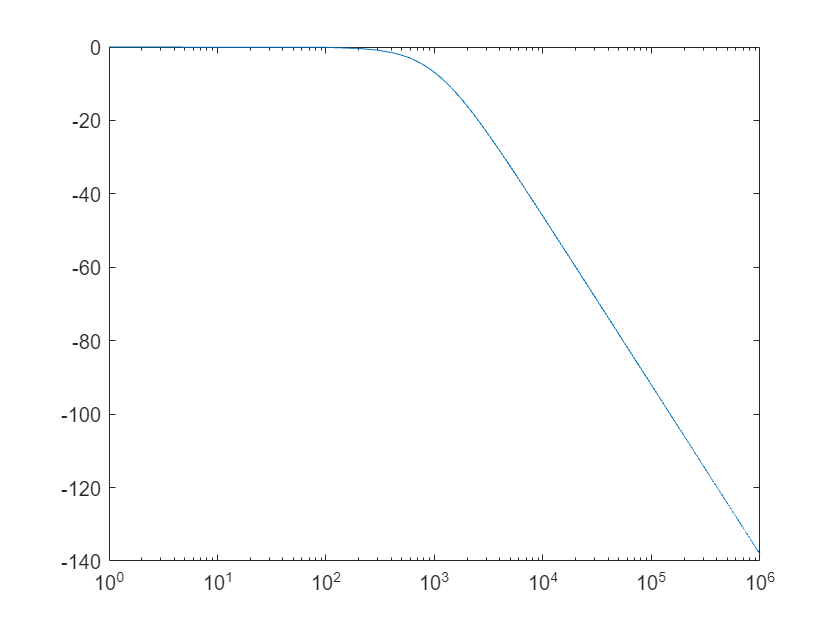

f_3dB = 592.1229

% Testing the simulator on two more circuits
fig2 = freqPlot('NetlistFig2.txt',2);

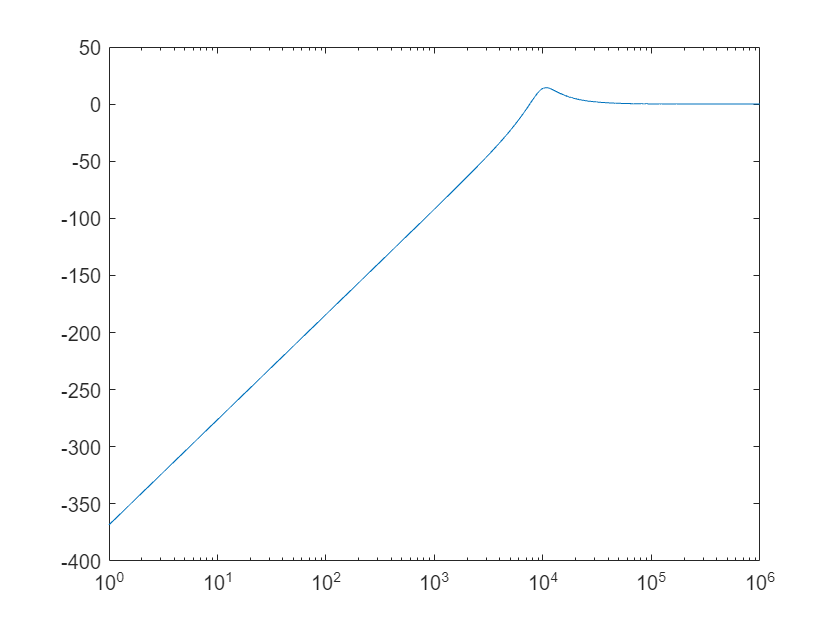

f_3dB = 1.3778e+04

fig3 = freqPlot('NetlistFig3.txt',3);